# Válogatott modellek a matematikai biológiában

# 2. gyakorlat

### Diffúzió egyenlet megoldása Dirichlet, Neumann és periodikus peremfeltételek mellett

Időbeli ($\tau$) ill. térbeli $(h)$ lépésközök megválasztása:

tau = 0.1;
h = 1;

Időhorizont amelyen vizsgálom a dinamikát (mintavételi pontok száma): 

nt = 500;

Kémcső / rúd / ált. közeg hossza:

L = 200;

Diffúzió sebessége:

D = 2;

Transzport sebessége (lehet negatív is). [ Érdekes számok: -5,-3,-2,2,3,4. ]

v = 1;

A diszkretizációt követően az egyenletben szereplő $\mu = D \frac{\tau}{h^2}$ és $\nu = \frac{\tau v}{h}$ értékei, melyek a következő diffúziós mátrixban szerepelnek:

syms mu nu
sor = [1-2*mu+nu mu-nu zeros(1,3)];
oszlop = [1-2*mu+nu mu zeros(1,3)];
A = toeplitz(oszlop,sor);
A(1) = 1-mu+nu;
A(end) = 1-mu

$$A = \left(\begin{array}{ccccc} \nu -\mu +1 & \mu -\nu & 0 & 0 & 0\\ \mu & \nu -2\,\mu +1 & \mu -\nu & 0 & 0\\ 0 & \mu & \nu -2\,\mu +1 & \mu -\nu & 0\\ 0 & 0 & \mu & \nu -2\,\mu +1 & \mu -\nu \\ 0 & 0 & 0 & \mu & 1-\mu \end{array}\right)$$

mu = D*tau/h^2

mu = 0.2000

nu = v*tau/h

nu = 0.1000

Emlékezzünk, a diszkretizáció eredménye:


$$u_{i+1,j} = u_{i,j-1} + (1-2\mu + \nu) u_{i,j} + u_{i,j+1}$$


Vizsgált pontok a térdimenzió mentén, illetve a vizsgált pontok száma:

x = 1:h:L;
nx = length(x);

A teljes $u(t,x)$ függvény numerikus közelítésének mátrix alakja, $U = \big(u_{i,j}\big)_{i=1,\dots,n_t,\,j=1,\dots,n_x}$

U = zeros(nx,nt);

Lehetséges kezdeti feltételek

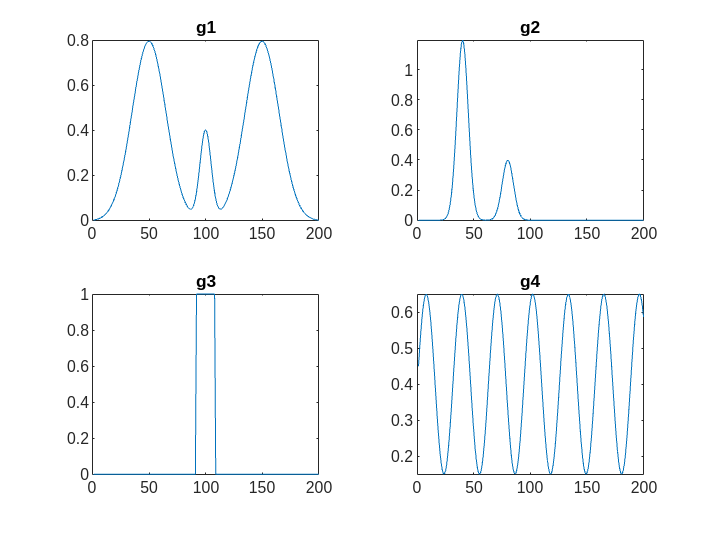

g1 = normpdf(x,L/4,15)*30 + normpdf(x,L/2,5)*5 + normpdf(x,3*L/4,15)*30;
g1 = g1 - min(g1);

g2 = normpdf(x,1*L/5,5)*15 + normpdf(x,2*L/5,5)*5;
g2 = g2 - min(g2);

g3 = zeros(nx,1);
g3(round(6*nx/13):round(7*nx/13)) = 1;

g4 = 0.4+sin(1/5*x)/4;

fig = figure(1);
delete(fig.Children)
nexttile; plot(x,g1); title g1
nexttile; plot(x,g2); title g2
nexttile; plot(x,g3); title g3
nexttile; plot(x,g4); title g4

sor = [1-2*mu+nu mu-nu zeros(1,nx-2)];
oszlop = [1-2*mu+nu mu zeros(1,nx-2)];
A = toeplitz(oszlop,sor);

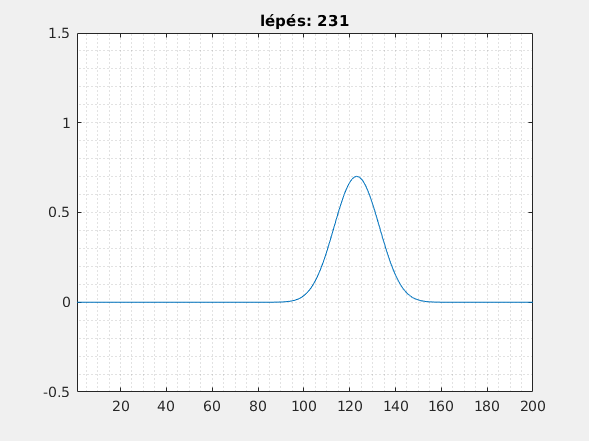

A(1) = 1-mu+nu;
A(end) = 1-mu;

fig = figure;
fig.Visible = 'on';

u = g3;
Pl = plot(x,u);
grid(gca, 'minor');
ylim([-0.5 1.5]);
xlim([1, 200]);
Tl = title(['lépés: ', num2str(1)]);

for i = 1:nt
    u = A*u;

    Pl.YData = u;
    Tl.String = ['lépés: ', num2str(i)];
    drawnow
     
    U(:,i) = u;
end

Ha az időbeli változásokat egyetlen ábrán szeretnénk látni, akkor a következőképpen készíthetünk egy 3D ábrát:

mesh(U);